L=10^-3; %H
C=10^-9; %F
R1=1*10^3; %Ohm
R2=2*10^3; %Ohm
A = [(-1/L)*(R1*R2)/(R1+R2) (-1/L)*(R2)/(R1+R2); (1/C)*(R2)/(R1+R2) (-1/C)*(1)/(R1+R2)];
B = [1/L; 0];
C = [(R1*R2)/(R1+R2) (R2)/(R1+R2)];
D = [0];
%State-space model
sys = ss(A, B, C, D,'StateName',{'Inductor current' 'Capacitance voltige'},'InputName','Input voltage','OutputName','Capacitance voltage');  

%TODO (0.5P) Does the MATLAB variable sys describe discrete or a continous-time model and why?
%Answer: According to MATLAB, it can do for both discrete and continous
%time, https://se.mathworks.com/help/control/ref/ss.html

%TODO (0.5P) Can the output of an RLC circuit depend on the future values
%of system state or on the future values of input?
%ANSWER: No

%TODO (1P) Is an the RLC circuit causal and why?
%ANSWER: Yes, because as state in the previous answer. it can not depend on
%future values.

%check the stability
pole(sys)

ans = 	1.0e+05 *

  -5.0000 + 6.4550i
  -5.0000 - 6.4550i


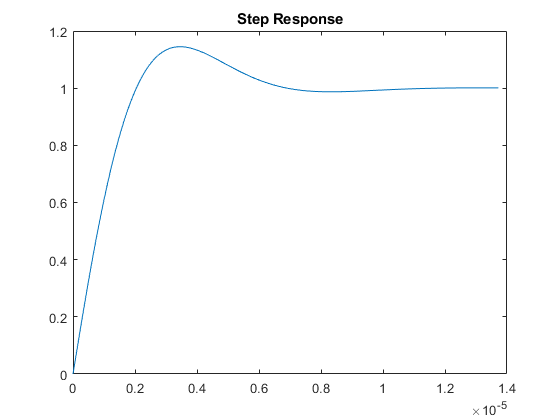

%TODO (1P) Is the system sys stable and why?
%ANSWER: The system is stable since it is a continous time system which is
%causal with poles in the left hand plane.

[y, t] = step(sys);
plot(t, y);
title('Step Response');

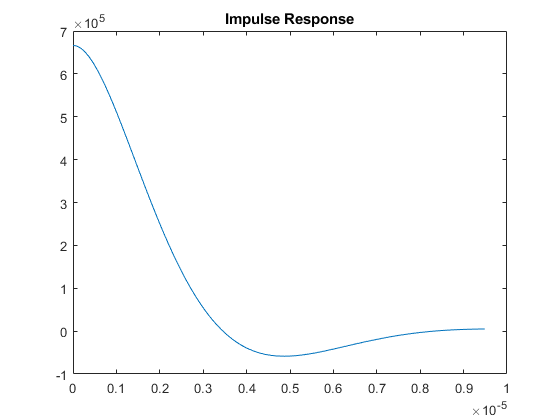

%TODO (1P) Why the step response stabilises on 1?
%ANSWER: Because the system is stable


%Impulse response
[y, t, x] = impulse(sys);
plot(t, y);
title('Impulse Response');

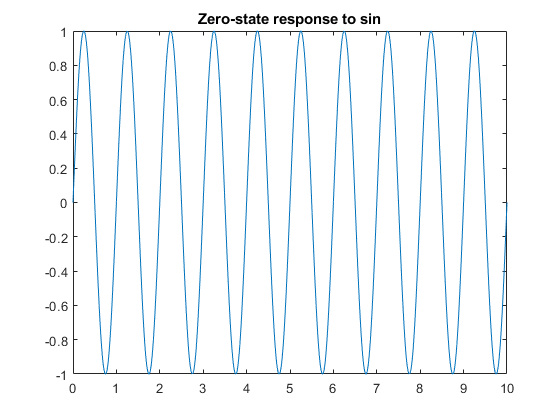

%TODO (1P) Why the impulse response stabilises on 0?
%ANSWER: Because the system is stable.

%Zero-state  response  to  a  sinusoidal input.
t = 0 : 0.001 : 10;
u = sin(2*pi*1*t); 
[y, t, x] = lsim(sys, u, t); 

plot(t, y); 
title('Zero-state response to sin');

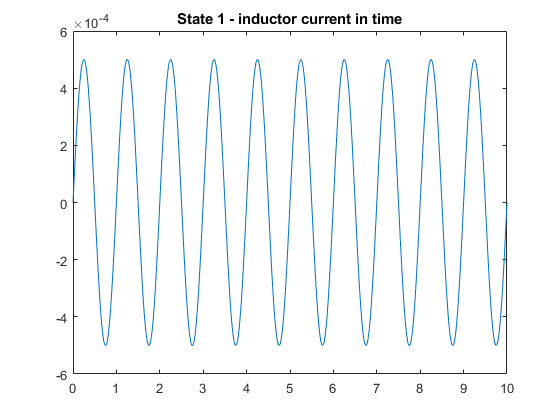


plot(t, x(:,1));
title('State 1 - inductor current in time');

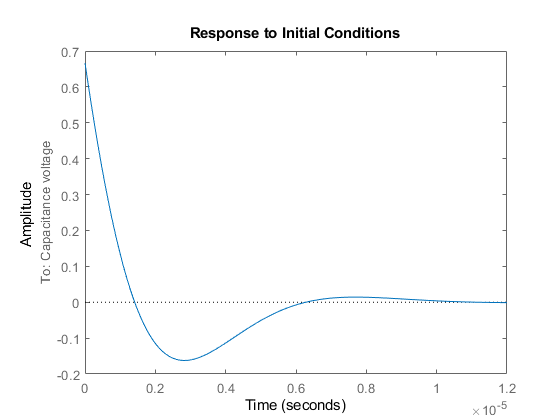


plot(t, x(:,2));
title('State 2 - capacitance voltage in time');

close all

%total response to a sin input plus initial condition (ZIR+ZSR)
t = 0 : 0.001 : 1;
initial(sys,[0, 1]);

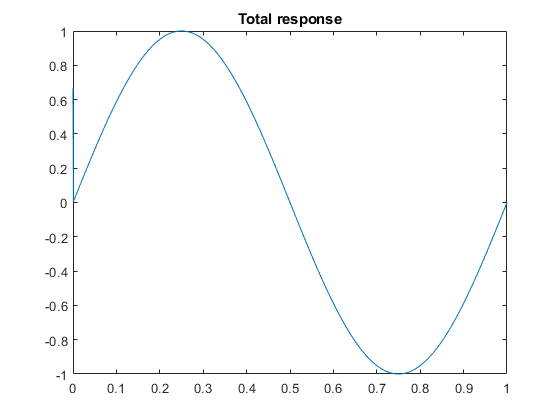

u = sin(2*pi*1*t); 
[y, t, x] = lsim(sys, u, t); 
[yInitial, tInitial]=initial(sys,[0, 1],t);

%total response is zero-state response plus zero-input response
yTotal=yInitial+y;
plot(t, yTotal); 
title('Total response');


%TODO (2P) Why the total response is the zero-state response plus the
%zero-input response?
%ANSWER: Because the zero input describes the system response to the
%initial conditions with the input set to 0. the zero state describes the
%system response to the input, when the initial conditions are 0. The
%complete system response is thus these two together, aka the sum of them.
